%% -------------------------
% Calculate additional intermediate parameters
%% -------------------------
free_space_loss_dB_arr = zeros(size(elev_angles_deg));
total_path_loss_dB_arr = zeros(size(elev_angles_deg));
N_dBW_arr = zeros(size(elev_angles_deg));

for i = 1:length(elev_angles_deg)
    elev_angle_degrees = elev_angles_deg(i);
    
    % Corrected slant range
    range_km = sqrt((Re_km + altitude_km)^2 - Re_km^2 * cosd(elev_angle_degrees)^2) ...
               - Re_km * sind(elev_angle_degrees);
    range_m = range_km*1e3;

    % Free-space path loss
    lambda_m = 3e8 / (freq_mhz*1e6);
    free_space_loss_dB_arr(i) = 20*log10(4*pi*range_m / lambda_m);

    % Total path loss
    total_path_loss_dB_arr(i) = free_space_loss_dB_arr(i) + sat_pointing_loss_dB + ...
                                polarization_loss_dB + atm_attenuation_dB;

    % Noise power
    k = 1.380649e-23;
    N_W = k * eff_noise_temp_K * B_noise_Hz;
    N_dBW_arr(i) = 10*log10(N_W);
end

%% -------------------------
% Create results table
%% -------------------------
results_table = table(elev_angles_deg', range_km_arr', free_space_loss_dB_arr', ...
    total_path_loss_dB_arr', rec_power_dBW_arr', N_dBW_arr', SNR_dB_arr', ...
    CNo_dBHz_arr', EbN0_dB_arr', link_margin_dB', ...
    'VariableNames', {'Elevation_deg', 'SlantRange_km', 'FSPL_dB', 'TotalLoss_dB', ...
    'RecPower_dBW', 'NoisePower_dBW', 'SNR_dB', 'CNo_dBHz', 'EbN0_dB', 'LinkMargin_dB'});

%% Display table
disp(results_table)

    Elevation_deg    SlantRange_km    FSPL_dB    TotalLoss_dB    RecPower_dBW    NoisePower_dBW    SNR_dB    CNo_dBHz    EbN0_dB    LinkMargin_dB
    _____________    _____________    _______    ____________    ____________    ______________    ______    ________    _______    _____________

          5             2077.1         151.6         151.6          -139.1          -160.82        21.717     64.728     34.728        25.128    
          6               1992        151.24        151.24         -138.74          -160.82        22.081     65.092     35.092        25.492    
          7             1911.3        150.88        150.88         -138.38 

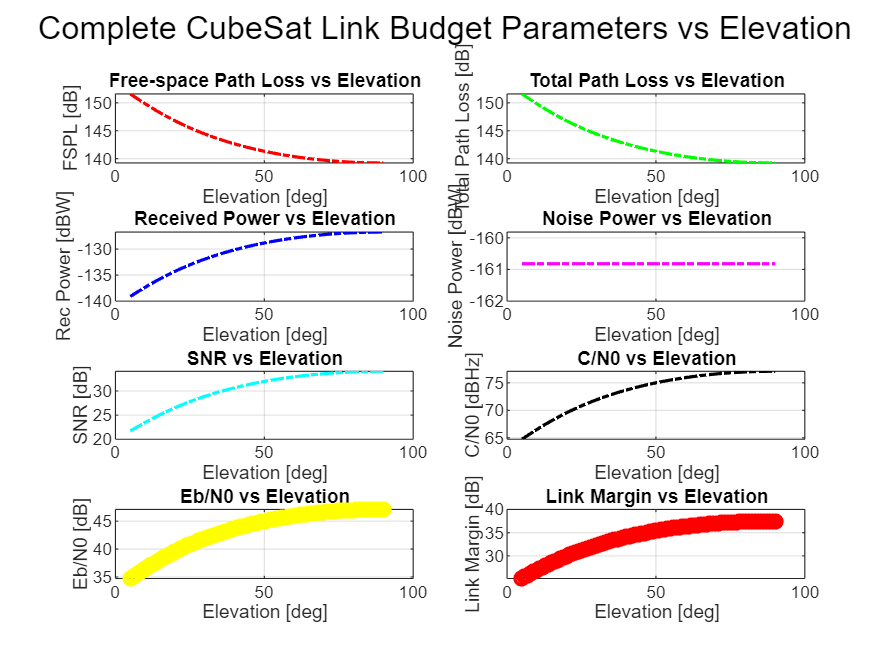


%% -------------------------
% Plot all parameters
%% -------------------------
figure;

subplot(4,2,1)
plot(elev_angles_deg, free_space_loss_dB_arr, 'r-.','LineWidth',1.5);
xlabel('Elevation [deg]'); ylabel('FSPL [dB]');
title('Free-space Path Loss vs Elevation'); grid on;

subplot(4,2,2)
plot(elev_angles_deg, total_path_loss_dB_arr, 'g-.','LineWidth',1.5);
xlabel('Elevation [deg]'); ylabel('Total Path Loss [dB]');
title('Total Path Loss vs Elevation'); grid on;

subplot(4,2,3)
plot(elev_angles_deg, rec_power_dBW_arr, 'b-.','LineWidth',1.5);
xlabel('Elevation [deg]'); ylabel('Rec Power [dBW]');
title('Received Power vs Elevation'); grid on;

subplot(4,2,4)
plot(elev_angles_deg, N_dBW_arr, 'm-.','LineWidth',1.5);
xlabel('Elevation [deg]'); ylabel('Noise Power [dBW]');
title('Noise Power vs Elevation'); grid on;

subplot(4,2,5)
plot(elev_angles_deg, SNR_dB_arr, 'c-.','LineWidth',1.5);
xlabel('Elevation [deg]'); ylabel('SNR [dB]');
title('SNR vs Elevation'); grid on;

subplot(4,2,6)
plot(elev_angles_deg, CNo_dBHz_arr, 'k-.','LineWidth',1.5);
xlabel('Elevation [deg]'); ylabel('C/N0 [dBHz]');
title('C/N0 vs Elevation'); grid on;

subplot(4,2,7)
plot(elev_angles_deg, EbN0_dB_arr, 'y-.','LineWidth',1.5);
xlabel('Elevation [deg]'); ylabel('Eb/N0 [dB]');
title('Eb/N0 vs Elevation'); grid on;

subplot(4,2,8)
plot(elev_angles_deg, link_margin_dB, 'r-.','LineWidth',1.5);
xlabel('Elevation [deg]'); ylabel('Link Margin [dB]');
title('Link Margin vs Elevation'); grid on;

sgtitle('Complete CubeSat Link Budget Parameters vs Elevation');